# Esercizio di Robotica Mobile

## Blocco Mobile Robot

clear; close all; clc;

% MOBILE ROBOT


## Blocco Environment

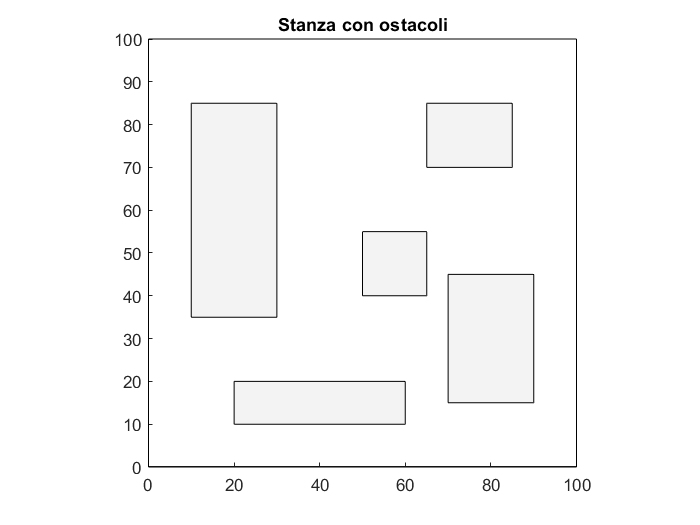

% ENVIRONMENT

% OSTACOLI
% ostacolo i = [sw; se; nw; ne]
% stanza
ostacoli = [0 0;100 0;0 100;100 100;];
% ostacolo 1 nella stanza
ostacoli = [ostacoli;10 35;30 35; 10 85;30 85];
% ostacolo 2 nella stanza
ostacoli = [ostacoli;20 10;60 10; 20 20;60 20];
% ostacolo 3 nella stanza
ostacoli = [ostacoli;50 40;65 40; 50 55;65 55];
% ostacolo 4 nella stanza
ostacoli = [ostacoli;70 15;90 15; 70 45;90 45];
% ostacolo 5 nella stanza
ostacoli = [ostacoli;65 70;85 70; 65 85;85 85];

% Plot stanza con ostacoli
figure(1); axis('equal'); axis([0 100 0 100]); title('Stanza con ostacoli')
rectangle('Position', [ostacoli(1,1) ostacoli(1,2) ...
    ostacoli(4,1)-ostacoli(1,1) ostacoli(4,2)-ostacoli(1,2)]);
for i=5:4:length(ostacoli)
    rectangle('Position', [ostacoli(i,1) ostacoli(i,2) ...
        ostacoli(i+3,1)-ostacoli(i,1) ostacoli(i+3,2)-ostacoli(i,2)], ...
        'FaceColor', '#f3f3f3');
end

% La seguente variabile costituisce il vettore dei punti che
% formano i bordi degli ostacoli
[stanza]=Costruisci_Stanza(ostacoli);

#### Scelta di posizione iniziale, goal ed orientamento

Seguire le istruzioni presenti nella command window per procedere.

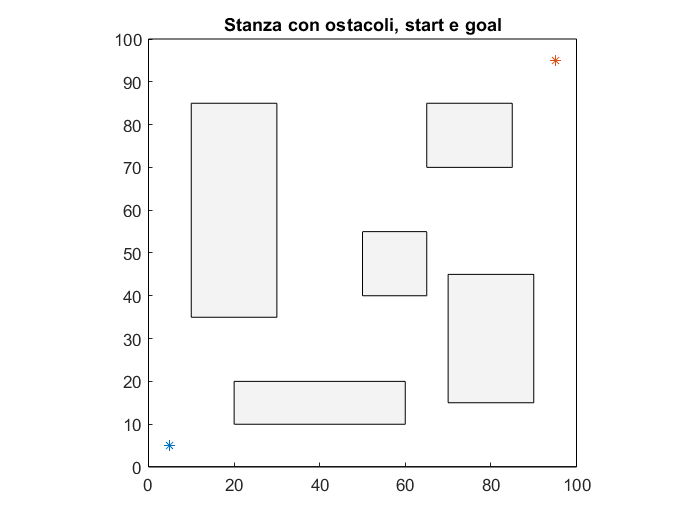

prompt = "Inserire i valori del punto di partenza 'SP=[x,y]', " + ...
    "del goal 'G=[x,y]' e dell'orientamento " + newline + ...
    "finale 'thetaG=x' (espresso in radianti)" + newline + " > SP = ";
SP = [5 5]; %input(prompt);
G = [95 95]; %input(" > G = ");
thetaG = pi/2; %nput(" > thetaG = ");

% Plot stanza con ostacoli, start e goal
figure(2); axis('equal'); axis([0 100 0 100]); hold on;
title('Stanza con ostacoli, start e goal');
rectangle('Position', [ostacoli(1,1) ostacoli(1,2) ...
    ostacoli(4,1)-ostacoli(1,1) ostacoli(4,2)-ostacoli(1,2)]);
for i=5:4:length(ostacoli)
    rectangle('Position', [ostacoli(i,1) ostacoli(i,2) ...
        ostacoli(i+3,1)-ostacoli(i,1) ostacoli(i+3,2)-ostacoli(i,2)], ...
        'FaceColor', '#f3f3f3');
end
plot(SP(1),SP(2),'*'); plot(G(1),G(2),'*');

## Blocco Planner

A questo punto si conoscono sia l'ambiente che i dati in input al sistema, quindi si può procedere con la progettazzione delle traiettorie.

Seguire le istruzioni presenti nella command window per procedere.

prompt = "Inserire il numero relativo alla tecnica che si vuole utilizzare:" ...
    + newline + " 1) Artificial Potential Fields" + newline + ...
    " 2) Discrete Potential Fields" + newline + " 3) Voronoi Diagrams" + ...
    newline + " 4) Visibility Graphs" + newline + "> ";
scelta_planner = 4; %input(prompt);

switch scelta_planner
    case 1
        [path]=Artificial_Potential_Fields(SP,G,stanza,ostacoli);
    case 2
        [path]=Discrete_Potential_Fields(SP,G,ostacoli);
    case 3
        [path]=Voronoi_Diagrams(SP,G,stanza,ostacoli);
end


utils.untitled()

Hello World
